
%% ex2_lorenz_chaos_attractor_demo.m
% Recitation Demo (Complex Systems): the Lorenz system as a canonical chaotic ODE.
%
% Focus:
%   - Phase space geometry (attractor and equilibria)
%   - Local linearization at equilibria (Jacobian eigenvalues)
%   - Sensitive dependence (numerical "Lyapunov exponent" estimate)
%   - Optional: Poincaré section (2D slice of 3D dynamics)
%
% System:
%   x' = sigma (y - x)
%   y' = x (rho - z) - y
%   z' = x y - beta z
%
% -------------------------------------------------------------------------

clear; close all; clc;

%% --------------------------- USER CONTROLS -----------------------------
P.sigma = 10;
P.rho   = 28;
P.beta  = 8/3;

Tend = 60;                 % integration time
x0   = [1; 1; 1];          % initial condition

doPoincare = true;         % set false to skip Poincaré section
zSection   = 25;           % plane z = zSection

% Two-trajectory sensitivity test
delta0 = 1e-6;             % small perturbation magnitude for chaotic divergence

%% ---------------------------- SIMULATION -------------------------------
opts = odeset('RelTol',1e-9,'AbsTol',1e-11,'MaxStep',0.02);

fprintf('Simulating Lorenz system with ode45...\n');

Simulating Lorenz system with ode45...


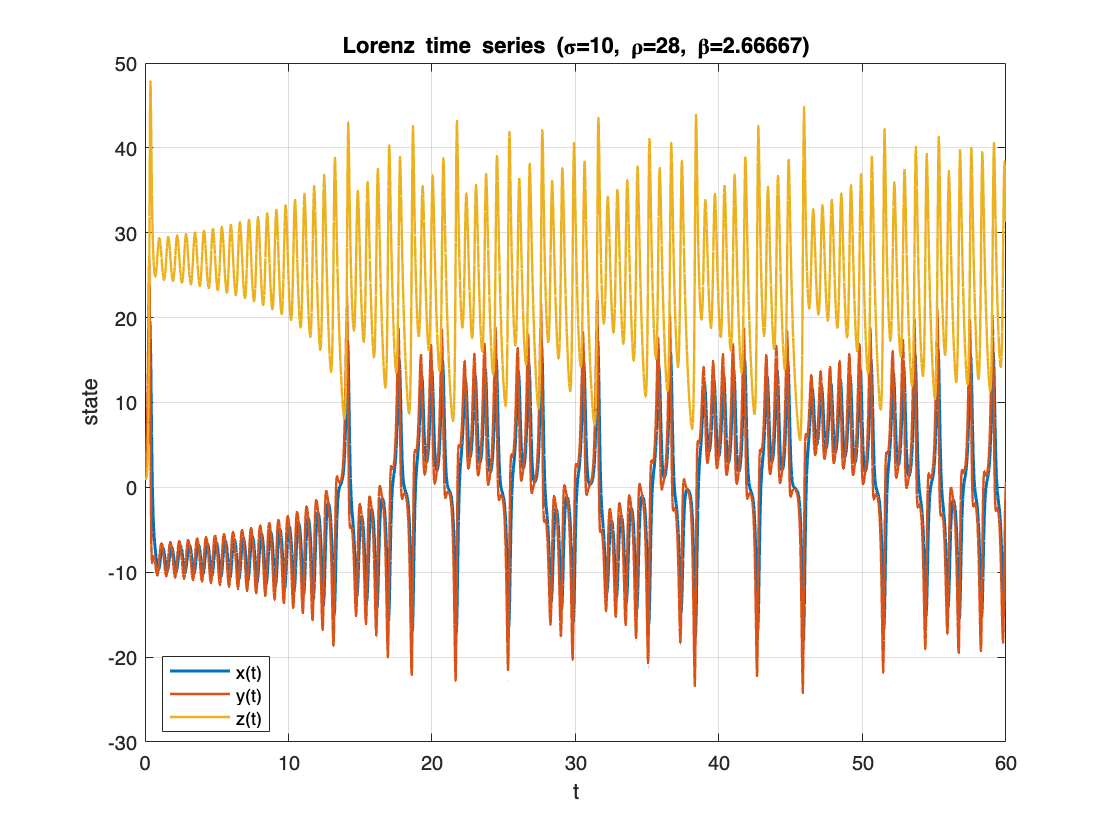

[t, X] = ode45(@(t,x) lorenz_rhs(t,x,P), [0 Tend], x0, opts);

x = X(:,1); y = X(:,2); z = X(:,3);

%% ------------------------ FIGURE 1: TIME SERIES ------------------------
figure('Name','Lorenz time series');
plot(t, x, 'LineWidth', 1.5); hold on;
plot(t, y, 'LineWidth', 1.2);
plot(t, z, 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('state');
legend('x(t)','y(t)','z(t)','Location','best');
title(sprintf('Lorenz time series (\\sigma=%g, \\rho=%g, \\beta=%g)',P.sigma,P.rho,P.beta));

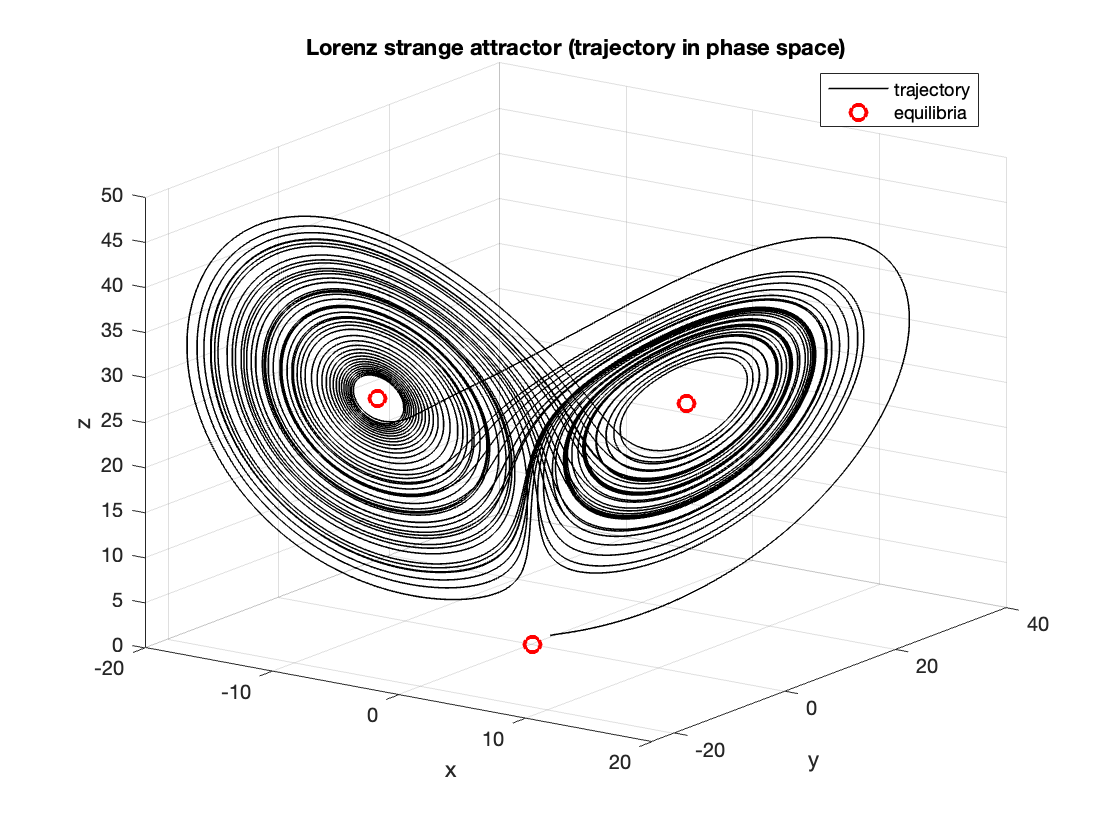


%% ------------------------ FIGURE 2: ATTRACTOR --------------------------
figure('Name','Lorenz attractor (3D phase space)');
plot3(x, y, z, 'k', 'LineWidth', 0.8); hold on; grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Lorenz strange attractor (trajectory in phase space)');
view(35,20);

% Mark equilibria (fixed points)
eq = lorenz_equilibria(P);
plot3(eq(:,1), eq(:,2), eq(:,3), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
legend('trajectory','equilibria','Location','best');


% [Insert slide image: 3D attractor with equilibria points]

%% -------------------- LOCAL LINEARIZATION (EQUILIBRIA) ------------------
% Jacobian of Lorenz:
%   J = [ -sigma,  sigma,   0
%          rho-z,    -1,   -x
%            y,      x,  -beta ]
%
% At equilibria, compute eigenvalues to discuss stability.

fprintf('\nEquilibria and Jacobian eigenvalues:\n');


Equilibria and Jacobian eigenvalues:


for k = 1:size(eq,1)
    xeq = eq(k,:)';
    J = lorenz_jacobian(xeq, P);
    eigJ = eig(J);
    fprintf('  Eq %d: (%.4f, %.4f, %.4f), eig = [% .4f%+.4fi, % .4f%+.4fi, % .4f%+.4fi]\n',...
        k, xeq(1), xeq(2), xeq(3), ...
        real(eigJ(1)), imag(eigJ(1)), real(eigJ(2)), imag(eigJ(2)), real(eigJ(3)), imag(eigJ(3)));
end

  Eq 1: (0.0000, 0.0000, 0.0000), eig = [-22.8277+0.0000i,  11.8277+0.0000i, -2.6667+0.0000i]
  Eq 2: (8.4853, 8.4853, 27.0000), eig = [-13.8546+0.0000i,  0.0940+10.1945i,  0.0940-10.1945i]
  Eq 3: (-8.4853, -8.4853, 27.0000), eig = [-13.8546+0.0000i,  0.0940+10.1945i,  0.0940-10.1945i]


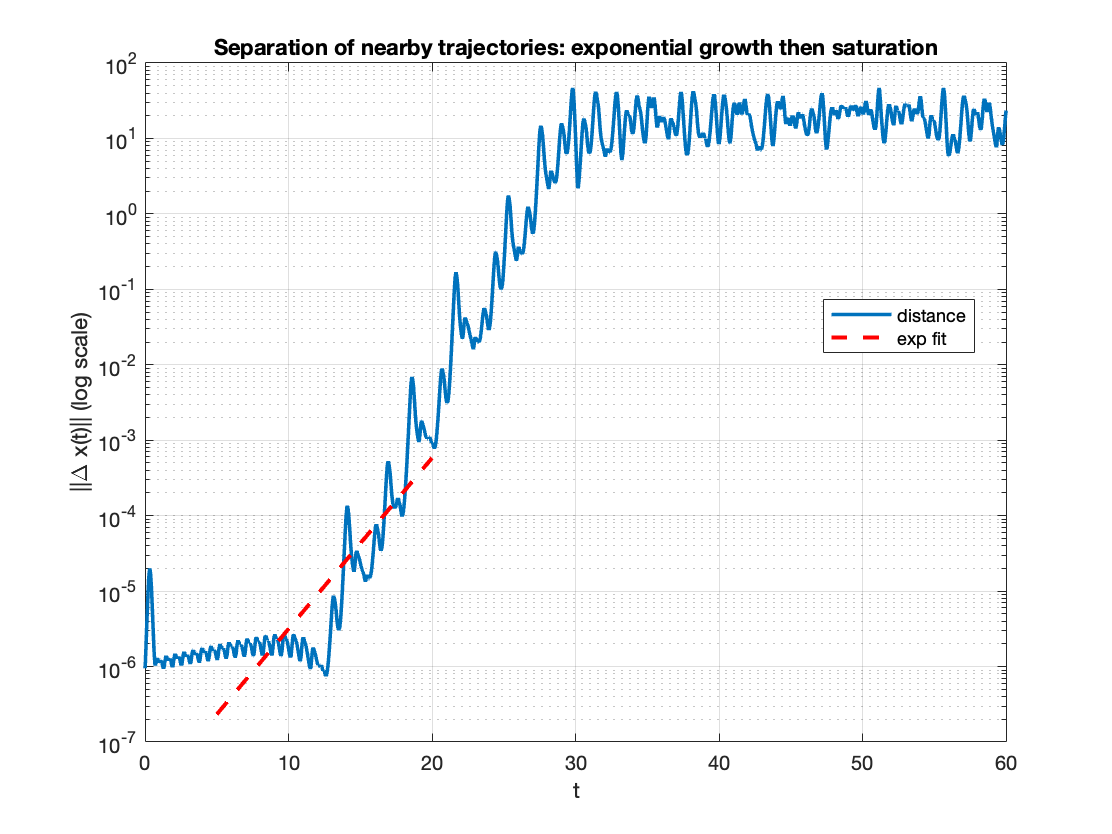


% Teaching note:
%   - For rho>1, origin becomes a saddle (one unstable direction).
%   - For classic rho=28, the two nonzero equilibria are also unstable (spiral saddles),
%     so trajectories are repelled from equilibria but remain bounded -> strange attractor.

%% --------------- SENSITIVE DEPENDENCE (TWO TRAJECTORIES) ----------------
% A quick numerical illustration:
%   Integrate two trajectories with initial conditions separated by delta0,
%   and examine how their separation grows.
%
% For chaotic systems, separation ~ exp(lambda t) for a while,
% where lambda is the largest Lyapunov exponent (LLE).
%
% NOTE: this is NOT a rigorous LLE algorithm; it is a teaching visualization.

x0a = x0;
x0b = x0 + delta0*[1;0;0];          % perturb only x

X0_2traj = [x0a; x0b];              % 6D combined system

[t2, X2] = ode45(@(t,u) two_lorenz_rhs(t,u,P), [0 Tend], X0_2traj, opts);

xa = X2(:,1); ya = X2(:,2); za = X2(:,3);
xb = X2(:,4); yb = X2(:,5); zb = X2(:,6);

dist = sqrt((xa-xb).^2 + (ya-yb).^2 + (za-zb).^2);

figure('Name','Sensitive dependence / Lyapunov estimate');
semilogy(t2, dist, 'LineWidth', 1.8); grid on;
xlabel('t'); ylabel('||\Delta x(t)|| (log scale)');
title('Separation of nearby trajectories: exponential growth then saturation');

% Estimate LLE by fitting log(dist) over an interval before saturation.
logd = log(dist);
% Choose a heuristic fitting window:
%   start after transient, end before saturation (when dist becomes O(1)).
tStartFit = 5;
tEndFit   = 20;

idx = (t2 >= tStartFit) & (t2 <= tEndFit) & isfinite(logd);

pfit = polyfit(t2(idx), logd(idx), 1);
lambda_est = pfit(1);

hold on;
dist_fit = exp(polyval(pfit, t2(idx)));
semilogy(t2(idx), dist_fit, 'r--', 'LineWidth', 2);
legend('distance','exp fit','Location','best');


fprintf('\nApprox. largest Lyapunov exponent (fit on [%g,%g]): lambda ~ %.3f\n', tStartFit, tEndFit, lambda_est);


Approx. largest Lyapunov exponent (fit on [5,20]): lambda ~ 0.522


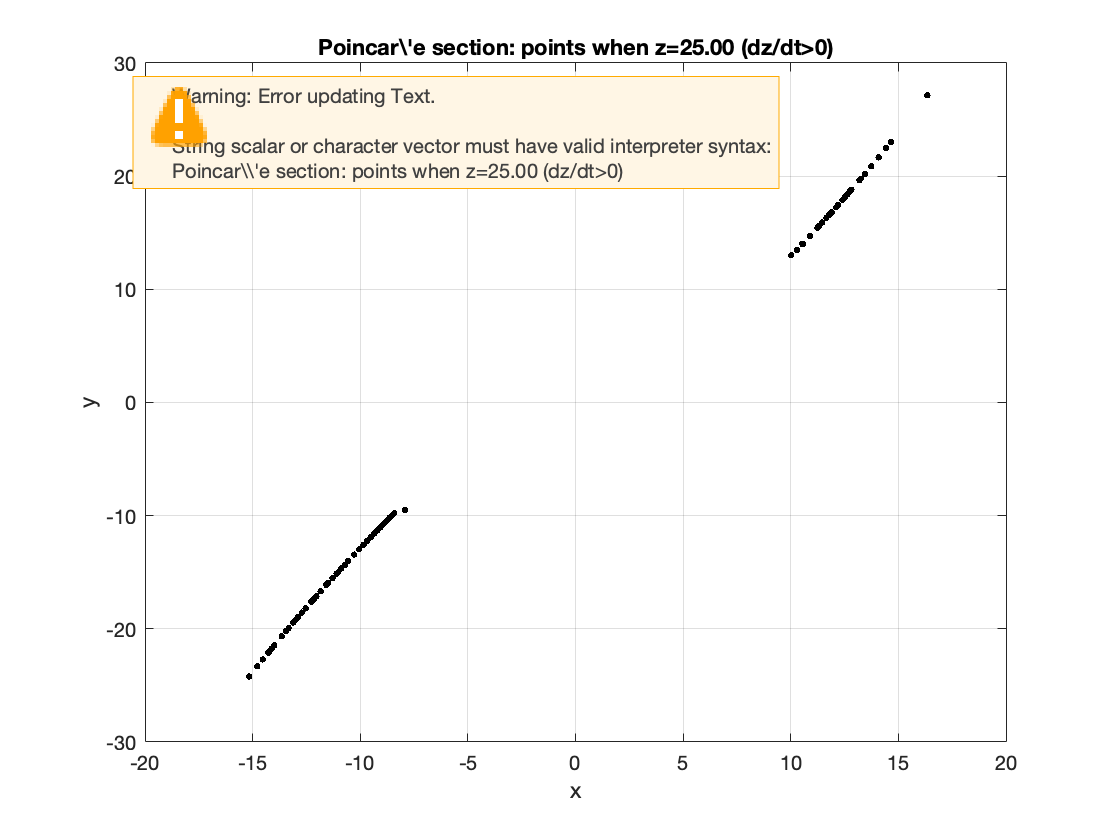


% [Insert slide image: semilogy separation + red fit line, annotated lambda]

%% --------------------- OPTIONAL: POINCARE SECTION -----------------------
if doPoincare
    % Record (x,y) when trajectory crosses plane z = zSection with dz/dt > 0
    % Use linear interpolation between time steps for nicer accuracy.
    Psec = poincare_section(t, X, zSection);

    figure('Name','Poincare section z=z0');
    plot(Psec(:,1), Psec(:,2), 'k.', 'MarkerSize', 8); grid on;
    xlabel('x'); ylabel('y');
    title(sprintf('Poincar\\''e section: points when z=%.2f (dz/dt>0)', zSection));
    % Interpretation: a strange attractor yields a fractal-like set in the section.
    % [Insert slide image: scattered/fractal-ish Poincare points]
end


%% ---------------------- TEACHING CHECKLIST -----------------------------
% Minimal slide set (if you want slides rather than live MATLAB):
%   [Slide 1] 3D attractor + equilibria points
%   [Slide 2] Sensitive dependence plot + estimated lambda
%   [Slide 3] (Optional) Poincaré section plot
%
% ------------------------------------------------------------------------
%% ----------------------------- FUNCTIONS --------------------------------

function dx = lorenz_rhs(~, x, P)
    dx = zeros(3,1);
    dx(1) = P.sigma*(x(2) - x(1));
    dx(2) = x(1)*(P.rho - x(3)) - x(2);
    dx(3) = x(1)*x(2) - P.beta*x(3);
end

function du = two_lorenz_rhs(t, u, P)
    % Two independent Lorenz systems stacked into one 6D system
    ua = u(1:3);
    ub = u(4:6);
    dua = lorenz_rhs(t, ua, P);
    dub = lorenz_rhs(t, ub, P);
    du = [dua; dub];
end

function eq = lorenz_equilibria(P)
    % Returns equilibria as rows: [x y z]
    eq = zeros(3,3);
    eq(1,:) = [0 0 0];
    if P.rho <= 1
        return;
    end
    r = sqrt(P.beta*(P.rho - 1));
    eq(2,:) = [ r,  r, P.rho - 1];
    eq(3,:) = [-r, -r, P.rho - 1];
end

function J = lorenz_jacobian(x, P)
    J = [ -P.sigma,   P.sigma,    0;
           P.rho-x(3),  -1,      -x(1);
           x(2),       x(1),    -P.beta ];
end

function Psec = poincare_section(t, X, z0)
    % Find crossings of z(t)=z0 with dz/dt>0 and interpolate (x,y).
    x = X(:,1); y = X(:,2); z = X(:,3);

    Psec = [];
    for k = 1:length(t)-1
        if (z(k) < z0 && z(k+1) >= z0)
            % linear interpolation fraction
            alpha = (z0 - z(k)) / (z(k+1) - z(k) + eps);
            xk = x(k) + alpha*(x(k+1)-x(k));
            yk = y(k) + alpha*(y(k+1)-y(k));

            % approximate dz/dt sign via forward difference
            dz = z(k+1) - z(k);
            if dz > 0
                Psec = [Psec; xk, yk]; %#ok<AGROW>
            end
        end
    end
end
